# Power-Split HEV for Speed Tracking

## High Speed Drive

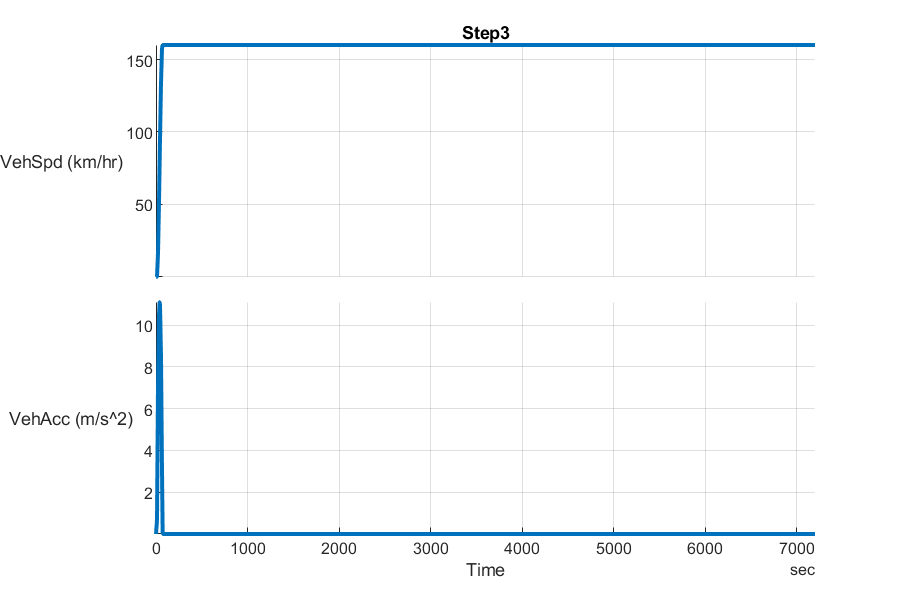

mdl = "PowerSplitHEV_system_model";

if not(bdIsLoaded(mdl))
  load_system(mdl);
end

% Use the speed tracking controller.
set_param(mdl+"/Controller & Environment", "ReferencedSubsystem", ...
  "PowerSplitHEV_SpeedTracking_refsub");

% Load defaults.
PowerSplitHEV_SpeedTracking_setup

% Load external input signals - speed reference
drvPtnSigBuilder = DrivePattern_InputSignalBuilder;
drvPtnSigBuilder.Plot_tf = true;

inpData = Step3(drvPtnSigBuilder, ...
  "VehSpdUnit", "km/hr", ...
  "VehSpd_1", 0, ...
  "VehSpd_2", 160, ...
  "VehSpd_3", 160, ...
  "VehSpd_1to2_ChangeStartTime", seconds(10), ...
  "VehSpd_1to2_ChangeEndTime", seconds(10 + 60), ...
  "VehSpd_2to3_ChangeStartTime", seconds(70 + 1), ...
  "VehSpd_2to3_ChangeEndTime", seconds(171 + 1), ...
  "StopTime", hours(2));

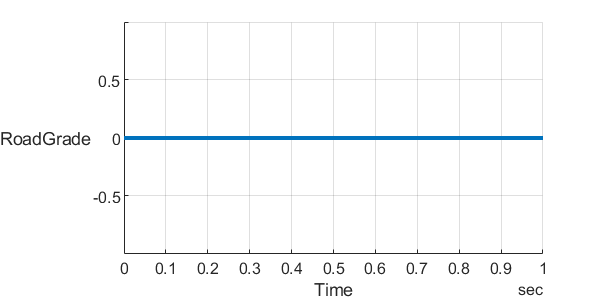


drivePatternFromWorkspace = inpData.Options.useFromWorkspace;

drivePattern_Signals = inpData.Signals;
drivePattern_Bus = inpData.Bus;

% Load external input signals - road grade
fig = figure;
[inputSignals, inputBus, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( ...
    "InputPattern", "flat", ...
    "PlotParent", fig );


inputSignals_RoadGrade = inputSignals;
inputBus_RoadGrade = inputBus;

% Set simulation time.
t_end = max(inpData.Options.StopTime_s, opt2.t_end)

t_end = 7200

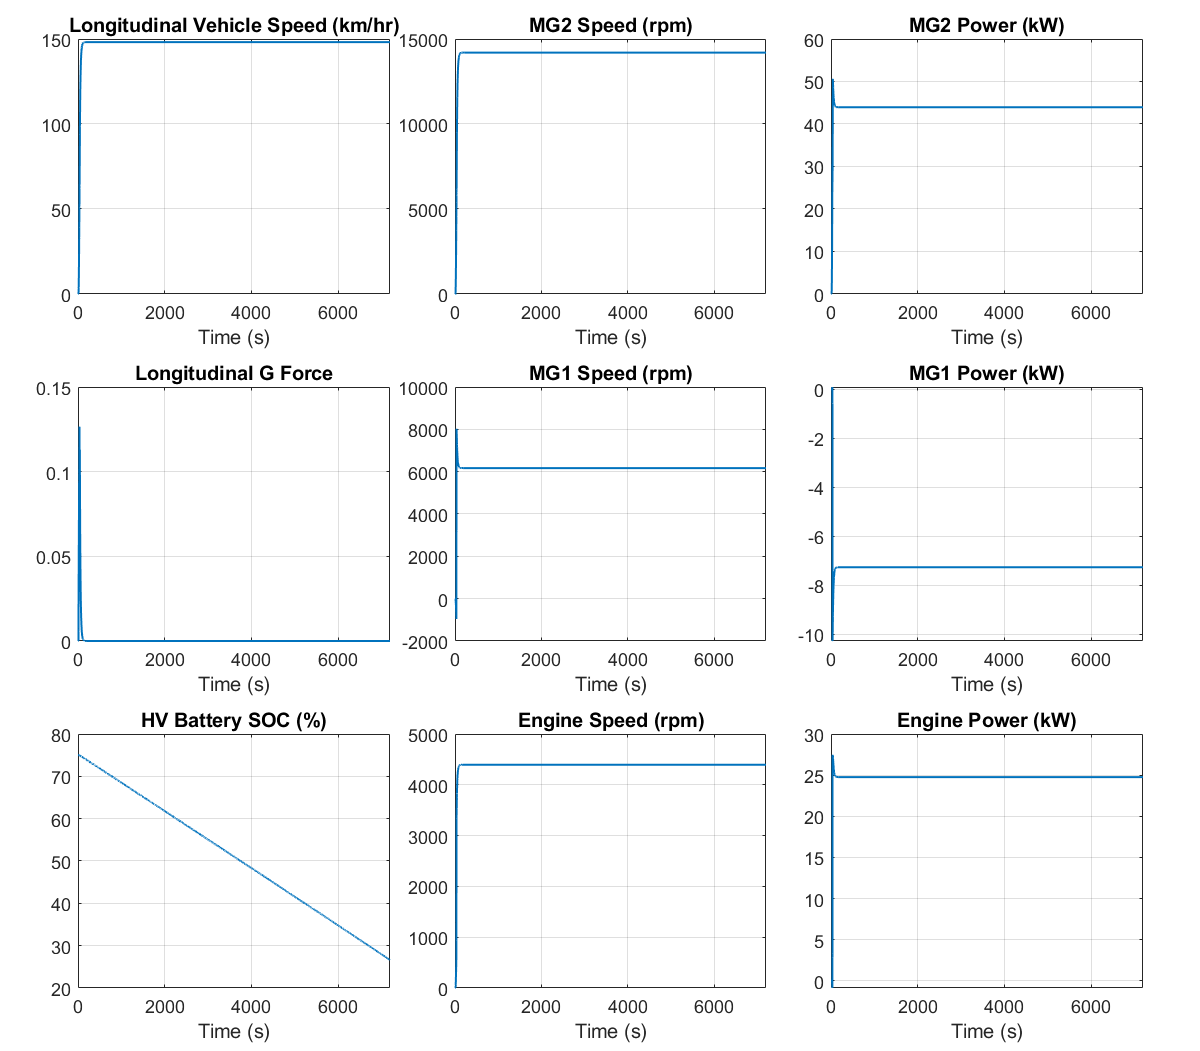

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, 'StopTime',num2str(t_end));

simOut = sim(simIn);

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_compact( ...
  "Dataset",simOut.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*